# 单原子链透射率与边界耦合的影响

clear;

N_point = 500;
% 链宽
Width = 3;

t = 4.5;
% 中间层原子数
layer = 3;
% 边界耦合
tr = 3;
epsilon_0 = 0;
eta = 1e-5;
% 本征能量
EigenEnergy = -2*t*cos((1:Width)*pi/(Width+1));
Iteration = 200;

## 导线哈密顿量

H00 = epsilon_0 * eye(Width) - t' * diag(ones(Width-1,1),-1) - t * diag(ones(Width-1,1),+1);
V = -t * eye(Width);
Iden = eye(Width);
tstart = tic;

## 画出对应subband的能带

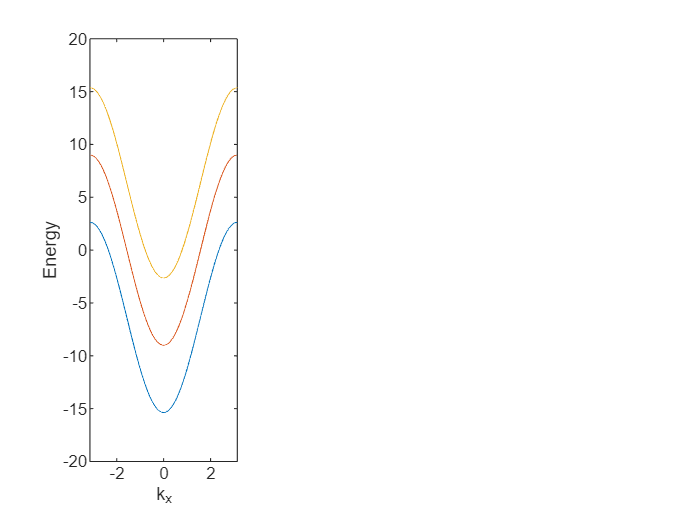

kx = linspace(-pi,pi,N_point);
energy_band = zeros(Width, length(kx));
% 中心区哈密顿量，测试用例导线模型
for ii = 1: length(kx)
    Hk = H00 + V * exp(1i*kx(ii)) + V' * exp(-1i*kx(ii));
    energy_band(:,ii) = eig(Hk);
end
figure(1)
subplot(1,3,1)
plot(kx, energy_band);
ax = gca;
Y_Lim = ax.YLim;
xlabel('k_x','Interpreter','tex')
ylabel('Energy')


energyscale = Y_Lim(2);
omega = linspace(-energyscale,energyscale,N_point);

## 格林函数计算电导

数值计算结果

中心区哈密顿量

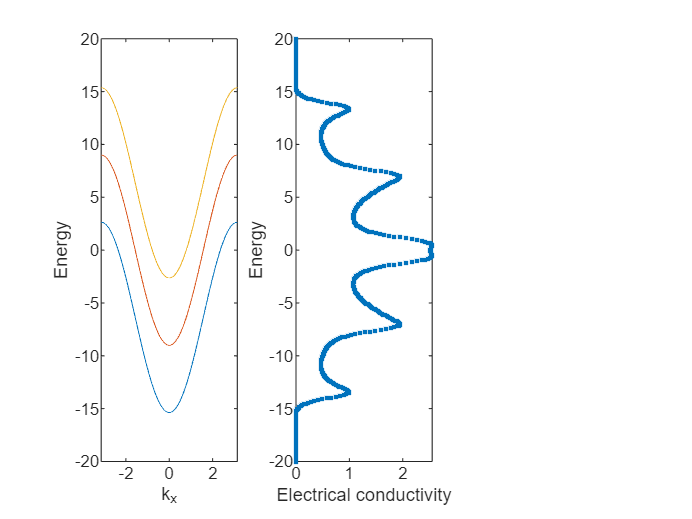

HCC = H00;

G_00_Right = zeros(Width, Width, length(omega));
G_00_Left = zeros(Width, Width, length(omega));
G_Centre_Ret = zeros(Width, Width, length(omega));
Transmission = zeros(1,length(omega));
% A_Spectral = zeros(1,length(omega));
for ii = 1:length(omega)
    G_00_Right(:,:,ii) = SurfaceGreenFunction(H00, V, omega(ii), Iteration);
    G_00_Left(:,:,ii) = SurfaceGreenFunction(H00, V', omega(ii), Iteration);

    Sigma_L = SurfaceGreenFunction_SelfEnergy(G_00_Left(:,:,ii), (tr/t) * V');
    Sigma_R = SurfaceGreenFunction_SelfEnergy(G_00_Right(:,:,ii), (tr/t) * V);

    Gamma_L = SurfaceGreenFunction_Broadening(Sigma_L);
    Gamma_R = SurfaceGreenFunction_Broadening(Sigma_R);


    G_Centre_Ret(:,:,ii) = SurfaceGreenFunction_Gcc_1L(HCC, V, layer, omega(ii), Sigma_L, Sigma_R);
    % A_Spectral(ii) = -1/pi*trace(imag(G_Centre_Ret));
    Transmission(ii) = real(GreenFunction_Transmission(Gamma_L, Gamma_R, G_Centre_Ret(:,:,ii)));
end
figure(1)
subplot(1,3,2)
plot(Transmission, omega,'.')
% plot(omega, Transmission)
ylabel('Energy')
xlabel('Electrical conductivity')

tfin = toc;
fprintf('The time used in Calculating transmission is %4.2f second\n', tfin-tstart)

The time used in Calculating transmission is 0.00 second


## 画出解析计算的结果

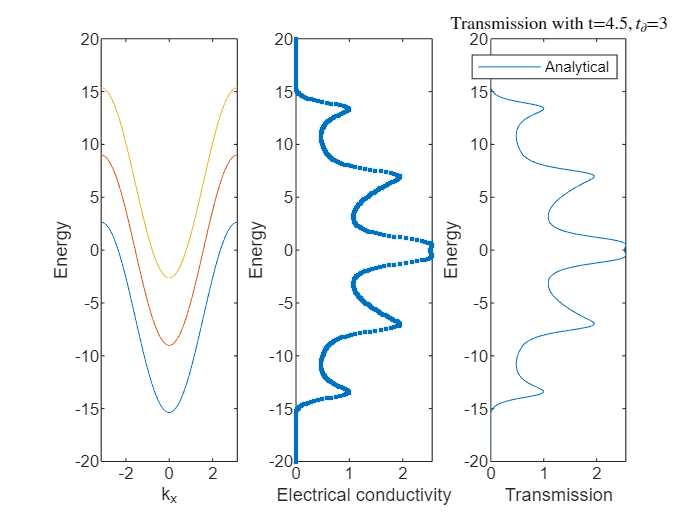

figure(1)
subplot(1,3,3)
Trans_Analy = zeros(1,length(omega));
AnalyTrans = @(omega) (abs(omega)<2*t).*(t^4 * tr^4 * (4*t^2 - omega.^2))./ ...
    ((t^2 * omega.^2 +tr^4 -tr^2 * omega.^2) .* (4* t^6 + omega.^2 *(-4*t^4 + 2*t^2* tr^2 + tr^4)+omega.^4 * (t^2-tr^2)) );
% Tr = tr/t;
% Omega = omega/t;
% AnalyTrans2 = (abs(Omega)<2).*(Tr^4 * (4 - Omega.^2))./ ((4+Omega.^2 * (Tr^4+2*Tr^2-4)+Omega.^4*(1-Tr^2)).*(Omega.^2-Omega.^2*Tr^2+Tr^4)   );
% plot(omega,Transmission, '.', omega, AnalyTrans,'--',Omega, AnalyTrans2,'-.')
for ii = 1:Width
    Trans_Analy = Trans_Analy + AnalyTrans(omega-EigenEnergy(ii));
end
plot(Trans_Analy, omega,'r')
% plot(omega,Transmission, '.', omega, AnalyTrans2,'-.')
% plot(omega, Transmission)
ylabel('Energy')
xlabel('Transmission')
legend('Analytical')
title(strcat(['Transmission with t=' num2str(t),'$, t_\partial$=', num2str(tr)]),'Interpreter','latex')


% plot(omega,squeeze(real(G_00_Left)))



t = 6.5;

tr = 6.5;
figure

for ii = 1:length(omega)
    G_00_Right(:,:,ii) = SurfaceGreenFunction(H00, V, omega(ii), Iteration);
    G_00_Left(:,:,ii) = SurfaceGreenFunction(H00, V', omega(ii), Iteration);

    Sigma_L = SurfaceGreenFunction_SelfEnergy(G_00_Left(:,:,ii), (tr/t) * V');
    Sigma_R = SurfaceGreenFunction_SelfEnergy(G_00_Right(:,:,ii), (tr/t) * V);

    Gamma_L = SurfaceGreenFunction_Broadening(Sigma_L);
    Gamma_R = SurfaceGreenFunction_Broadening(Sigma_R);


    G_Centre_Ret(:,:,ii) = SurfaceGreenFunction_Gcc_1L(HCC, V, layer, omega(ii), Sigma_L, Sigma_R);
    % A_Spectral(ii) = -1/pi*trace(imag(G_Centre_Ret));
    Transmission(ii) = real(GreenFunction_Transmission(Gamma_L, Gamma_R, G_Centre_Ret(:,:,ii)));
end
AnalyTrans = @(omega) (abs(omega)<2*t).*(t^4 * tr^4 * (4*t^2 - omega.^2))./ ...
    ((t^2 * omega.^2 +tr^4 -tr^2 * omega.^2) .* (4* t^6 + omega.^2 *(-4*t^4 + 2*t^2* tr^2 + tr^4)+omega.^4 * (t^2-tr^2)) );
Trans_Analy = zeros(1,length(omega));
for ii = 1:Width
    Trans_Analy = Trans_Analy + AnalyTrans(omega-EigenEnergy(ii));
end
plot(Transmission, omega,'.',  Trans_Analy, omega)
ax = gca;
ax.YLim = Y_Lim;
% plot(Transmission, omega,'.',  AnalyTrans(omega-t)+AnalyTrans(omega+t), omega)
% plot(omega,Transmission, '.', omega, AnalyTrans2,'-.')
% plot(omega, Transmission)
ylabel('Energy')
xlabel('Transmission')
legend('Numerical', 'Analytical','Normalized')

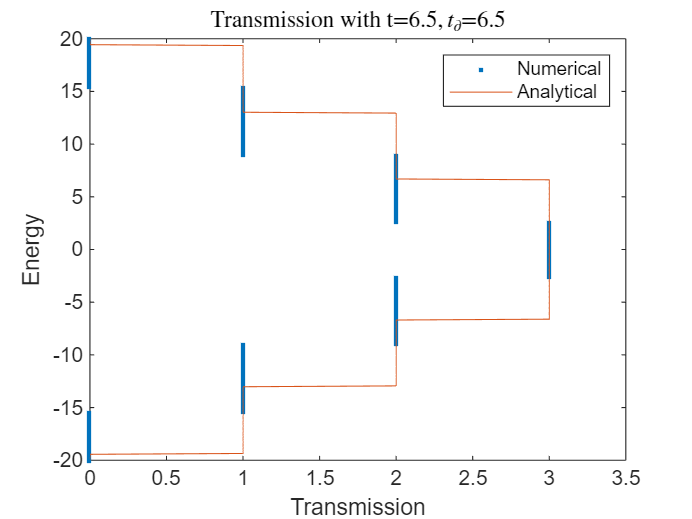

title(strcat(['Transmission with t=' num2str(t),'$, t_\partial$=', num2str(tr)]),'Interpreter','latex')